clear;
close all;
fprintf("Input values in SI units\n");

Input values in SI units


I1_ = 0.4;
I12 = 0;
I13 = 0;
I2_ = 0.3;
I21 = I12

I21 = 0

I23 = 0;
I31 = I13

I31 = 0

I32 = I23

I32 = 0

I3_ = 0.2;

w1_0_ = 15;
w2_0_ = 10;
w3_0_ = 0;
p = 10; %precision for time shift

%to find principle CS
I_ = [I1_ I12 I13; I21 I2_ I23; I31 I32 I3_];
w_0_ = [w1_0_; w2_0_; w3_0_];
[R, I] = eig(I_);  %R is rotation matrix
if I(1,1)<I(2,2)
    %swapping 1,2 cols
    R(:,[1,2]) = R(:,[2,1]);
    %swapping I11 and I22
    temp = I(1,1);
    I(1,1) = I(2,2);
    I(2,2) = temp;
end
if I(2,2)<I(3,3)
    %swapping 2,3 cols
    R(:,[2,3]) = R(:,[3,2]);
    %swapping I22 and I33
    temp = I(2,2);
    I(2,2) = I(3,3);
    I(3,3) = temp;
end
if I(1,1)<I(2,2)
    %swapping 1,2 cols
    R(:,[1,2]) = R(:,[2,1]);
    %swapping I11 and I22
    temp = I(1,1);
    I(1,1) = I(2,2);
    I(2,2) = temp;
end
I

I =     0.4000         0         0
         0    0.4000         0
         0         0    0.2000


R

R =      0     1     0
     1     0     0
     0     0     1


e1 = transpose(R)*[1; 0; 0];
e2 = transpose(R)*[0; 1; 0];
e3 = transpose(R)*[0; 0; 1];
%transpose(R)*I*R %should return I_
w_0 = transpose(R)*w_0_

w_0 =     10
    15
     0


w1_0 = w_0(1,1);
w2_0 = w_0(2,1);
w3_0 = w_0(3,1);
I1 = I(1,1);
I2 = I(2,2);
I3 = I(3,3);

%to find angular momentum
K = vpa((I1*w1_0^2 + I2*w2_0^2 + I3*w3_0^2)/2,20)

$$K = 65.0$$

H = vpa(sqrt(((I1*w1_0)^2 + (I2*w2_0)^2 + (I3*w3_0)^2)),20)

$$H = 7.2111025509279785862$$

H1_0 = (I1*w1_0)/sqrt(2*K*I2);
H2_0 = (I2*w2_0)/sqrt(2*K*I2);
H3_0 = (I3*w3_0)/sqrt(2*K*I2);
d_ = H^2/(2*K*I2);
a_ = sqrt(abs(I2*d_-I3)/(I2-I3));
b_ = sqrt(abs(I1-I2*d_)/(I1-I2));

syms t0;
syms t;
if d_<1  %a_<b_ or d_<1 or D<I2
    fprintf("Case1");
    t0 = (invJacobiSNfunction.mijsn(-H2_0/a_,(a_/b_)^2))*(-1/b_)*sqrt(I1*I3/((I1-I2)*(I2-I3)));
    E_(t) = b_*(t-t0)*sqrt((I1-I2)*(I2-I3)/(I1*I3));
    H2_(t) = -a_*jacobiSN(E_(t), (a_/b_)^2);
    H1_(t) = a_*sqrt(I1*(I2-I3)/(I2*(I1-I3)))*jacobiCN(E_(t),(a_/b_)^2);
    H3_(t) = b_*sqrt(I3*(I1-I2)/(I2*(I1-I3)))*jacobiDN(E_(t),(a_/b_)^2);
    if vpa(H3_(0)*H3_0,10) < 0 %The sign of H3_0 is different from H3_(0).
        fprintf("inside");
        H3_(t) = -H3_(t);
        H1_(t) = -H1_(t);
    end
elseif d_>1 %a_>b_ or d_>1 or D>I2
    fprintf("Case2");
    t0 = (invJacobiSNfunction.mijsn((-H2_0/b_),(b_/a_)^2))*(-1/a_)*sqrt(I1*I3/((I1-I2)*(I2-I3)));
    E_(t) = a_*(t-t0)*sqrt((I1-I2)*(I2-I3)/(I1*I3));
    H2_(t) = -b_*jacobiSN(E_(t), (b_/a_)^2);
    H1_(t) = a_*sqrt(I1*(I2-I3)/(I2*(I1-I3)))*jacobiDN(E_(t),(b_/a_)^2);
    H3_(t) = b_*sqrt(I3*(I1-I2)/(I2*(I1-I3)))*jacobiCN(E_(t),(b_/a_)^2);
    if vpa(H3_(0)*H3_0,10) < 0 
        fprintf("inside");
        H3_(t) = -H3_(t);
        H1_(t) = -H1_(t);
    end
else %a_=b_ or d_=1 or D=I2
    fprintf("Case3");
    t0 = (atanh(-H2_0/a_))*(-1/a_)*sqrt(I1*I3/((I1-I2)*(I2-I3)));
    E_(t) = a_*(t-t0)*sqrt((I1-I2)*(I2-I3)/(I1*I3));
    H2_(t) = -a_*tanh(E_(t));
    H1_(t) = a_*sqrt(I1*(I2-I3)/(I2*(I1-I3)))/cosh(E_(t));
    H3_(t) = a_*sqrt(I3*(I1-I2)/(I2*(I1-I3)))/cosh(E_(t));
end

Case1

fprintf('%f',t0);

NaN

%t here is relative time i.e. t=actual_time*sqrt(2*K/I2)

%to find angular velocity
act_t = t*sqrt(I2/2*K);
w1(t) = H1_(t*sqrt(2*K/I2))*sqrt(2*K*I2)/I1;
w2(t) = H2_(t*sqrt(2*K/I2))*sqrt(2*K*I2)/I2;
w3(t) = H3_(t*sqrt(2*K/I2))*sqrt(2*K*I2)/I3;
H_(t) = sqrt((H1_(t*sqrt(2*K/I2))^2 + H2_(t*sqrt(2*K/I2))^2 + H3_(t*sqrt(2*K/I2))^2)*2*K*I2);
K_(t) = ((H1_(t*sqrt(2*K/I2))^2)/I1 + (H2_(t*sqrt(2*K/I2))^2)/I2 + (H3_(t*sqrt(2*K/I2))^2)/I3)*K*I2;
save analyticalsoln.mat w1 w2 w3 I1 I2 I3 w1_0 w2_0 w3_0 H_ K_

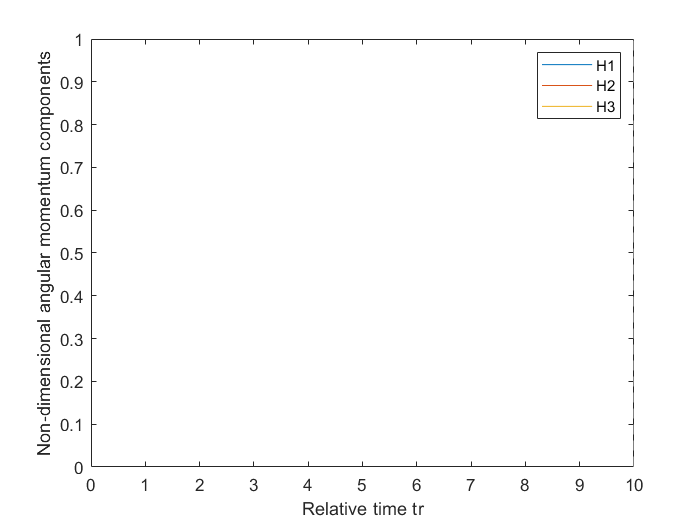

%plotting 'H1','H2','H3'
tend=10;
fplot(H1_ , [0 tend]);
hold on;
fplot(H2_ , [0 tend]);
fplot(H3_ , [0 tend]);
legend('H1','H2','H3');
ylabel('Non-dimensional angular momentum components')
xlabel('Relative time tr');
hold off;

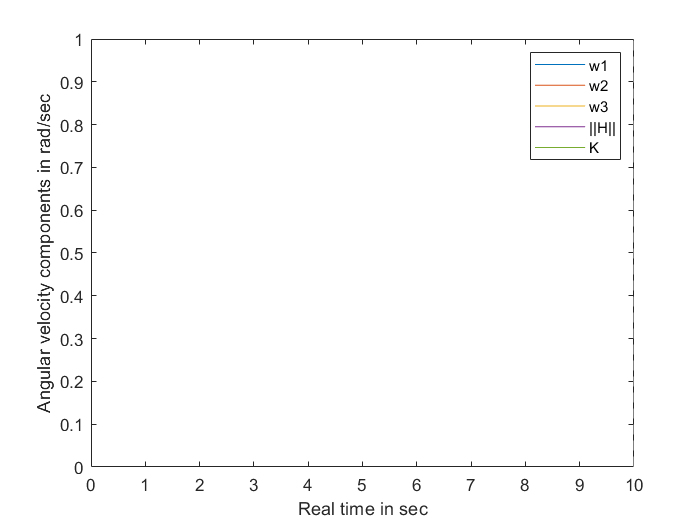

%plotting 'w1', 'w2', 'w3', '||H||', 'K'
tend=10;
fplot(w1, [0 tend]);
hold on;
fplot(w2, [0 tend]);
fplot(w3, [0 tend]);
fplot(H_, [0 tend]);
fplot(K_, [0 tend]);
legend('w1', 'w2', 'w3', '||H||', 'K');
xlabel('Real time in sec');
ylabel('Angular velocity components in rad/sec');
hold off;